# Using simulink to investigate the impact of non-linear components on position system behaviour

The control101 toolbox focuses mainly on linear models and thus simple MATLAB code is sufficient to illustrate the core behaviours. However, the real world is full of more complex components and connections. In such cases writing code can be messy or difficult and it is often easier to capture the scenario using tools such as simulink.

This resource focuses on non-linear behaviour which will arise from some common non-linear components:

- Input saturation   (inputs always have rate and absolute limits)

- Backlash in motors

- Measurement delays

The easiest way to explore this is using the app interface (see section 3) ***nonlinear_position_control.mlapp***, although this livescript provides source code that users will find helpful to take more explicit control of the simulation.

The intention is to expose users to the non-linear components and their impact on closed-loop behaviour.  Underlying the virtual laboratory (app file) is a simulink file  ***non_linear_Position_system_control101.slx***  which users could open for interest. Take a copy in your own area if you want to edit this for further study.

### Similar files and the toolbox

See website below for more files like this.    [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, University of Sheffield                         

## Preamble

Many simulink files have a large number of parameters which are most conveniently defined with a supporting MATLAB script and thus one might as well run the simulink file directly from the same script. This resource collects the core parameter values from the workspace and a step input component, runs the simulation and then the outputs are sent back to the workspace for plotting.

## Table of contents

- Simple position system models

- Simulink model and simulation.

- The app file

## 1. Simple position system models

The angular displacement of the DC motor is translated into a linear movement by means of a mechanical transmission chain. The input voltage* u* applied to the armature circuit of the motor is supplied by an analogue controller based on the tracking error *e* between the prescribed reference *z* and the position *y* of the tool. The measured position *ym* of the tool is obtained by means of a potentiometer based transducer. A schematic of this system is given below in Figure 1 and the equivalent block diagram is given in Figure 2. 

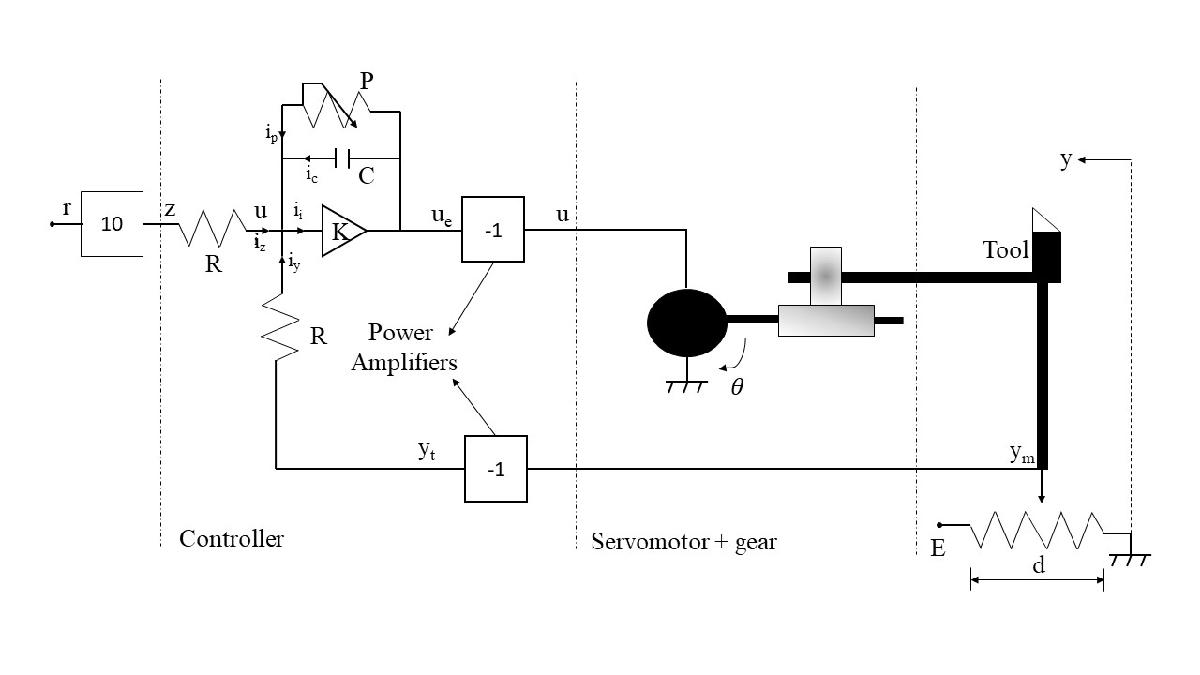

**Figure 1.1**. Schematic of positioning system

### 1.1 Simple mathematical models for the position system

The corresponding transfer function models are not derived here, but rather just symmarised as this still shows the dependence on the different system components.

$G_c \left(s\right)=\frac{\frac{1}{\textrm{RC}}}{s+\frac{1}{\textrm{PC}}}$;       $G_m \left(s\right)=\frac{k_m k_s }{s}$;     $G_t =\frac{E}{d}$;  $\overset{\ldotp }{\theta} =k_s u;$    ${y=k}_m \theta$.

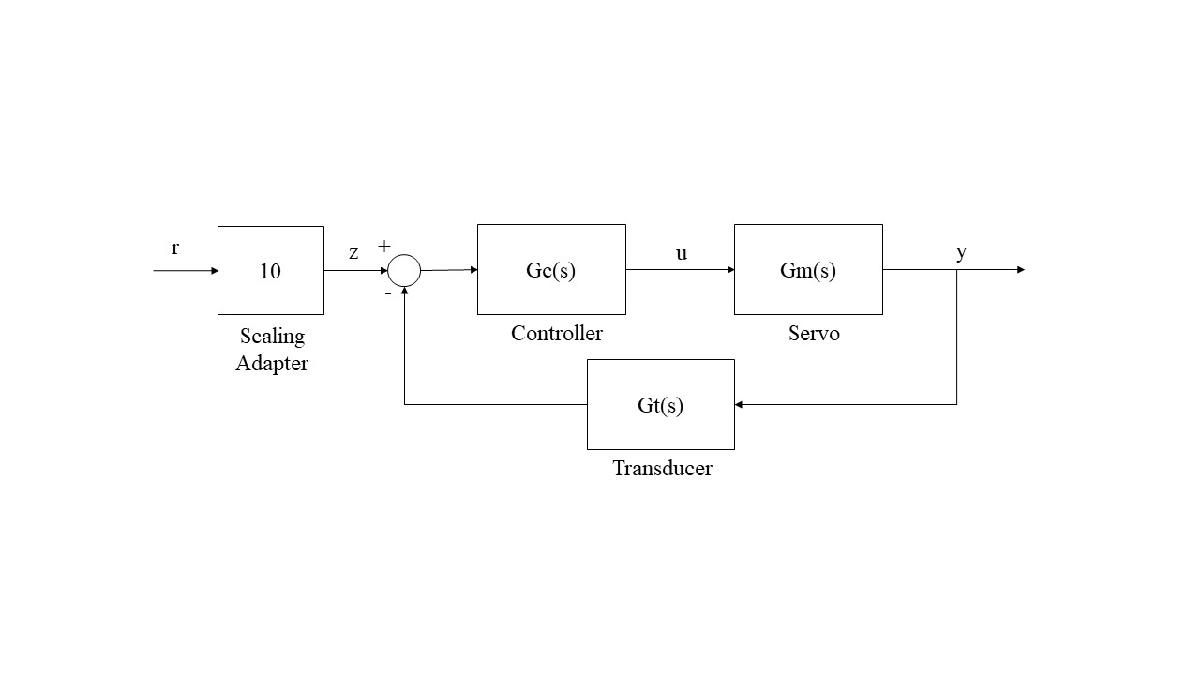

**Figure 1.2**. Block diagram representation of the positioning system

**Remark**: Readers will note that this is a closed-loop system and as the servo includes an integrator, already delivers reasonable behaviour and thus control design is not a focus on this resource.

### 1.2 Non-linear components within the system

There are several possible sources of non-linearity which are described here in turn. The user is able to decide whether to include or exclude these components in order to facilitate and investigation of their impact on behaviour. Figure 1.3 shows that the simulink diagram and includes switches which allow the user to run the simulation with or without the different non-linear components. The settings for each these will be clear in the code snippets used to run the simulation.

- Input saturation   (inputs always have rate and absolute limits).

- Backlash in motors.

- Measurement delays (minimimum of 0.01 to avoid simulink warnings).

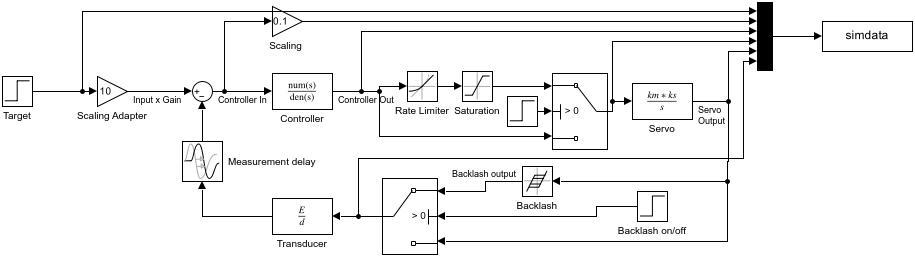

**Figure 1.3**: Screen capture of*** non_linear_Position_System_control101.slx.*** 

% to open simulink file 
% open non_linear_Position_System_control101.slx

%print(['-snon_linear_Position_System_control101'],'-djpeg',['non_linear_Position_System_control101.jpg'])

## 2. Simulink files and simulation

Code snippets are used to define the data needed by the simulation file, to run the simulation and then to produce neat plots.  This section gives several examples of such snippets for convenience, but of course readers should then be empowered to change these as desired. Alternatively use the app interface which allows a good range of sensible simulation options.

### 2.1 No non-linearity

To remove non-linearity, set all the switches to have a value of zero as seen in the code below.

disp('*****************************')

*****************************


disp('Section 2.1 illustrations below')

Section 2.1 illustrations below


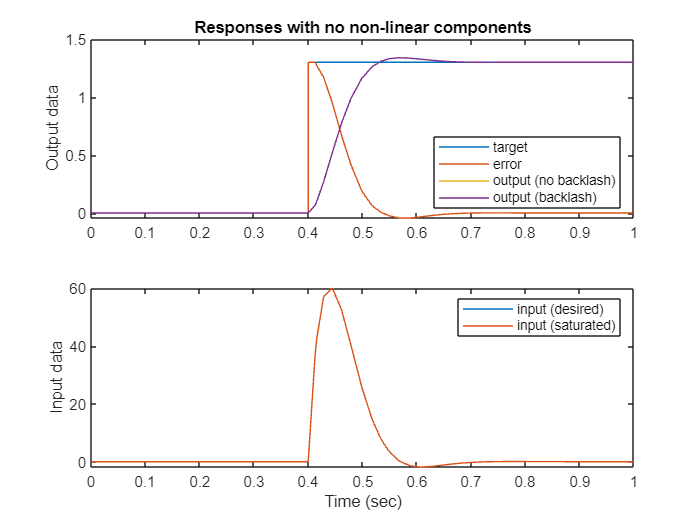


% define default parameter values
R=10E3;
P=60E3;
C=0.33E-6;
ks=52.5;
km=5E-3;
E=10;
d=1;
endtime=1;  % Simulation runtime

% Non-linear component definitions
deadband=0.2;  % Backlash
backlashonoff  =0; % 0 means off
umax=50;     % Saturation limits
umin=-50;
Dumax  =200;  % rate limit per second
Dumin=-200;
saturationonoff = 0;  % 0 means no saturation
measurementdelay=0.01;  % use of zero gives simulink warnings

% Simulation - 
sim("non_linear_Position_System_control101.slx")
tt=simdata.time;
yy = simdata.signals.values; % stored in order as shown in Figure 1.3

% Plotting
subplot(211)
plot(tout,yy(:,[1,2,5,6]));
legend('target','error','output (no backlash)','output (backlash)','Location','southeast')
title('Responses with no non-linear components')
ylabel('Output data')
subplot(212)
plot(tout,yy(:,[3,4]));
legend('input (desired)','input (saturated)')
ylabel('Input data')
xlabel('Time (sec)')

### 2.2 Adding saturation

Real systems have limits on the available power/voltage/current and so forth. The next file gives a very small extension whereby a saturation block is added to the controller signal. Otherwise running this file and viewing results is the same procedure as earlier. The figures/scope clearly show the difference between the demanded signal 'u' and the delivered 'u' which is saturated at 10.

disp('*****************************')

*****************************


disp('Section 2.2 illustrations below')

Section 2.2 illustrations below


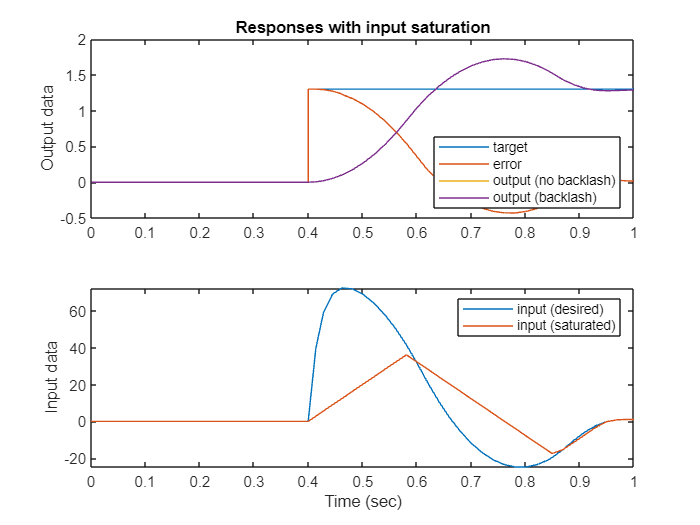


% Non-linear component definitions
backlashonoff  =0; % 0 means off
saturationonoff = 1;  % 1 means include saturation
measurementdelay=0.01;

% Simulation - 
sim("non_linear_Position_System_control101.slx")
tt=simdata.time;
yys = simdata.signals.values; % stored in order as shown in Figure 1.3

% Plotting
figure
subplot(211)
plot(tout,yys(:,[1,2,5,6]));
legend('target','error','output (no backlash)','output (backlash)','Location','southeast')
title('Responses with input saturation')
ylabel('Output data')
subplot(212)
plot(tout,yys(:,[3,4]));
legend('input (desired)','input (saturated)')
ylabel('Input data')
xlabel('Time (sec)')

### 2.3 Adding backlash

Real gearing systems are often subject ot backlash and thus non-linear behaviours during changes in direction. The next example illustrates the impact of such a component. it would be straightforward to augment the input singal from a step to investigate this behaviour more generally.

disp('*****************************')

*****************************


disp('Section 2.3 illustrations below')

Section 2.3 illustrations below


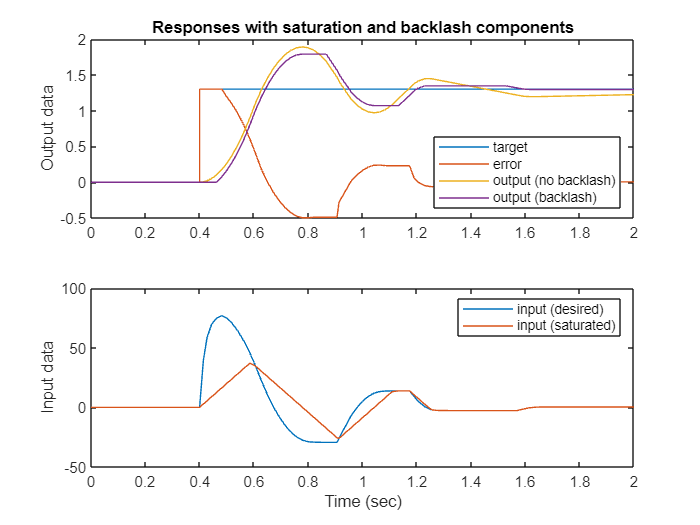


% Non-linear component definitions
backlashonoff  =1; % 0 means on
saturationonoff = 1;  % 1 means include saturation
measurementdelay=0.01;
endtime=2;

% Simulation - 
sim("non_linear_Position_System_control101.slx")
tt=simdata.time;
yysb = simdata.signals.values; % stored in order as shown in Figure 1.3

% Plotting
figure
subplot(211)
plot(tout,yysb(:,[1,2,5,6]));
legend('target','error','output (no backlash)','output (backlash)','Location','southeast')
title('Responses with saturation and backlash components')
ylabel('Output data')
subplot(212)
plot(tout,yysb(:,[3,4]));
legend('input (desired)','input (saturated)')
ylabel('Input data')
xlabel('Time (sec)')

### 2.4 Adding measurement delay

Real gearing systems are often subject ot backlash and thus non-linear behaviours during changes in direction. The next example illustrates the impact of such a component. it would be straightforward to augment the input singal from a step to investigate this behaviour more generally.

disp('*****************************')

*****************************


disp('Section 2.4 illustrations below')

Section 2.4 illustrations below


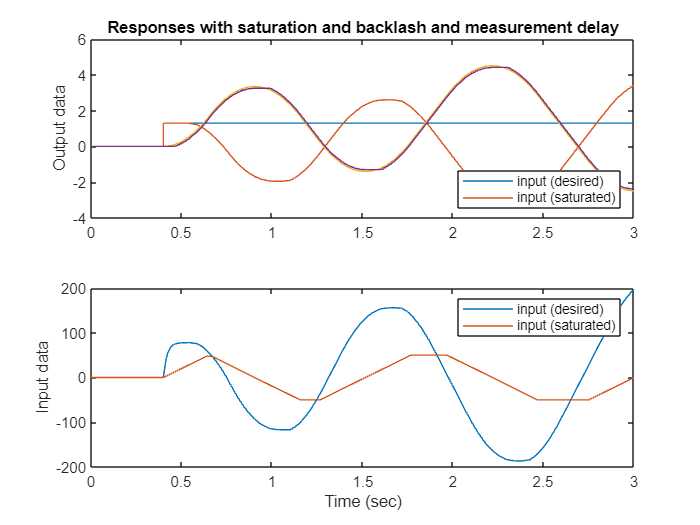


% Non-linear component definitions
backlashonoff  =1; % 0 means off
saturationonoff = 1;  % 1 means include saturation
measurementdelay=0.1;
endtime=3;

% Simulation - 
sim("non_linear_Position_System_control101.slx")
tt=simdata.time;
yysbd = simdata.signals.values; % stored in order as shown in Figure 1.3

% Plotting
figure
subplot(211)
plot(tout,yysbd(:,[1,2,5,6]));
legend('target','error','output (no backlash)','output (backlash)','Location','southeast')
title('Responses with saturation and backlash and measurement delay')
ylabel('Output data')
subplot(212)
plot(tout,yysbd(:,[3,4]));
legend('input (desired)','input (saturated)')
ylabel('Input data')
xlabel('Time (sec)')

## 3. The app file

The app file provides a more interactive interface which hides the coding so users can concentrate on the impact of different choices of the non-linear components. This allows users to change:

- the input limits.

- the dead band in the backlash component.

- the measurement delay.

Users can also switch off these effects altogether. Figure 3.1 shows a screen capture of the app from which it should be self evident what users can do.

- Use the sliders to change the values of the non-linear components.

- Use the buttons to turn on and off inclusion of the nonlinear effect; red means the non-linear compionent is ignored.

- Press 'create responses' to add new data to the figures.

The two left hand figures keep track of the simulations and record the data selected in the legend (a value of zero means the relevant non-linearity is not included) so that users can do systematic studies of the impact of different choices. A new study can be started by selecting the refresh figure button.

The right hand figures show all the loop signals (see Figure 1.3) for the current simulation only.

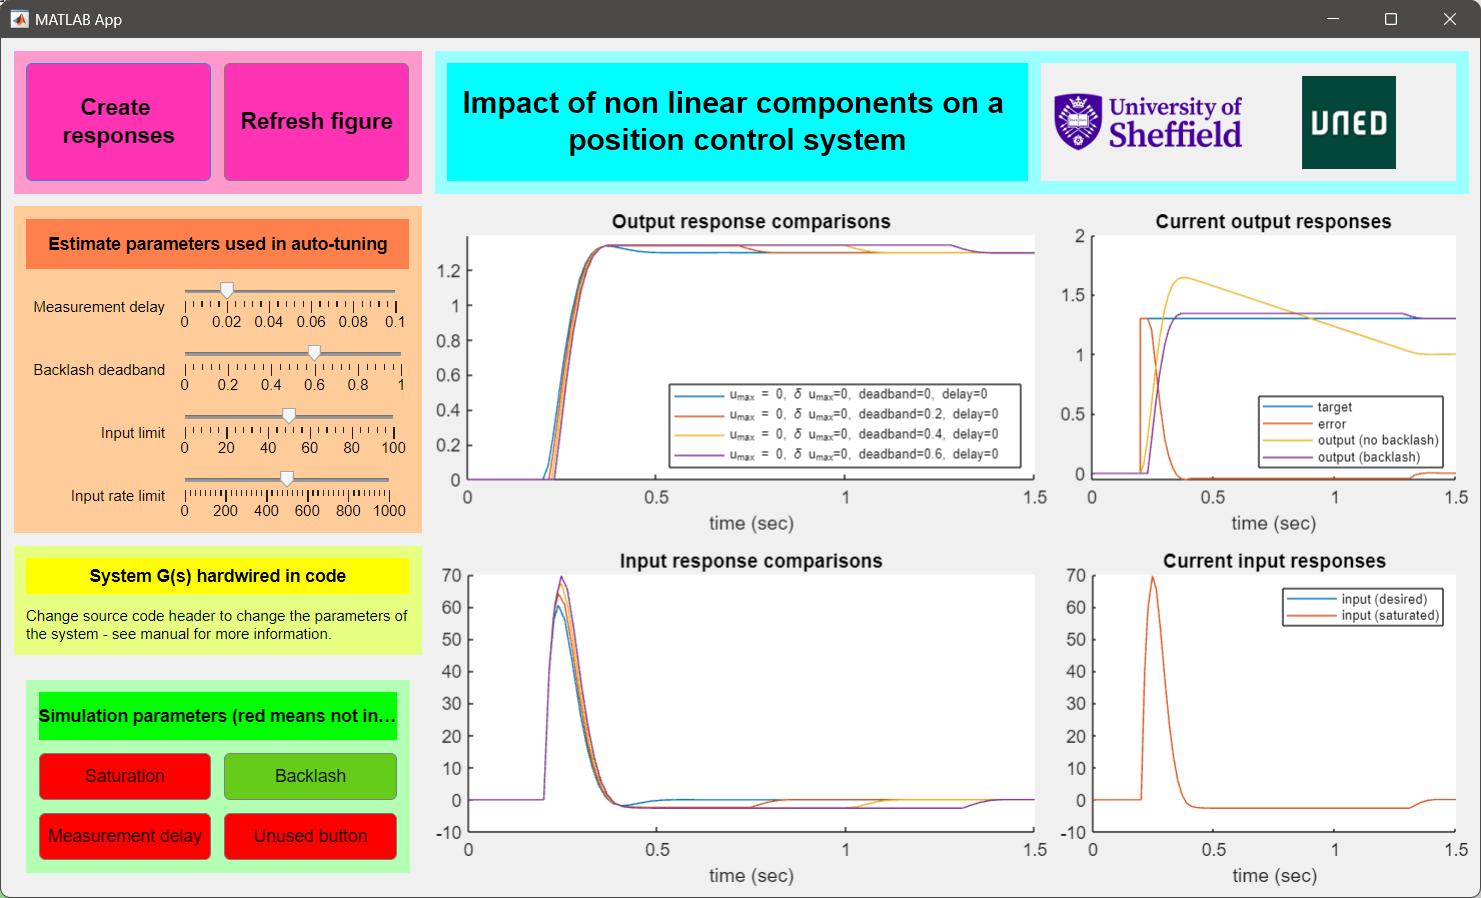

**Figure 3.1**: Screen capture of the app